# Drone Control with pid dynamics

clc;
clear;
clear all;
clf;

#### Map definition and obstacles plot

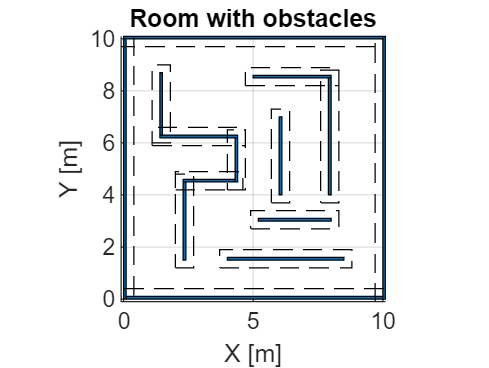

x_map_size = 10;
y_map_size = 10;
field_of_view = 5;

[obstacles, inflated_obstacles] = map_definition;

figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Room with obstacles');
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);

#### Build the RRT algorith to explore the space (ONE STEP TIME EXAMPLE)

% Parameter declaration
step_size = 0.3; 
n_iterations = 10; 
goal_threshold = 0.5; 

% RRT initialization

start = [rand() * x_map_size, rand() * y_map_size]; % absolute poi from wich the drone starts the simulation

while isInObstacle(start, inflated_obstacles)
    start = [rand() * x_map_size, rand() * y_map_size];
end

rrt_tree = start; % RRT starting point
rrt_relative_tree = [0 , 0];
parent_indices = 0; % RRT parent index

% RRT tree generation
for i = 2:n_iterations % from 2-> starting point at the moment is given
    % If point is inside the obstacles, avoid

    flag1 = true;
    flag2 = true;
    while flag1 == true || flag2 == true

        % Random point (MODIFY HERE THE EXPLORATION SPACE FOR EACH DRONE IF REQUIRED)
        random_point = [rand() * x_map_size, rand() * y_map_size];

        if isInObstacle(random_point, inflated_obstacles)
            flag1 = true;
        else
            flag1 = false;
        end

        % Find nearest point wrt RRT tree
        distances = sqrt(sum((rrt_tree - random_point).^2, 2));
        [min_distance, nearest_idx] = min(distances);

        % Identify new RRT point
        direction = random_point - rrt_tree(nearest_idx, :);
        unit_direction = direction / norm(direction);
        new_point = rrt_tree(nearest_idx, :) + step_size * unit_direction;

        % Check compenetrarion of new point wrt the obstacles
        if isInObstacle(new_point, inflated_obstacles)
            flag2 = true;
        else
            flag2 = false;
        end

    end

    % Add the new point to the RRT tree
    rrt_tree = [rrt_tree; new_point];
    rrt_relative_tree = [rrt_relative_tree; new_point-start];
   
    parent_indices = [parent_indices; nearest_idx];

    % % Verify if the goal is reached
    % if norm(new_point - goal) < goal_threshold
    %     disp('Goal raggiunto!');
    %     break;
    % end
end


#### Plot the RRT

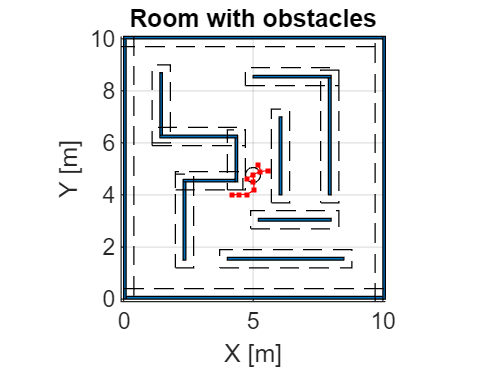

figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Room with obstacles');
hold on;
PLOT_MAP(obstacles, inflated_obstacles, 10, 10);
RRT_PLOT(rrt_tree, parent_indices);
hold off;

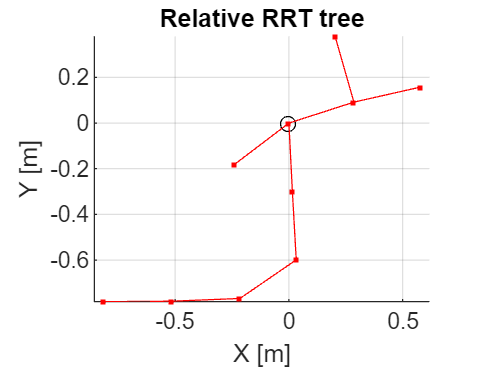


figure();
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
title('Relative RRT tree');
RRT_PLOT(rrt_relative_tree, parent_indices);

## LiDAR test example

lidar_position = start;
lidar_angles = linspace(0, 360, 100);  % 100 scanning lines
max_range = 2;
lidar_dist_res = 0.01; 
[point_abs,point_abs_clean, point_rel, dist_rel] = Lidar_scan(obstacles, lidar_position, lidar_angles, max_range, lidar_dist_res);

Plot Lidar example

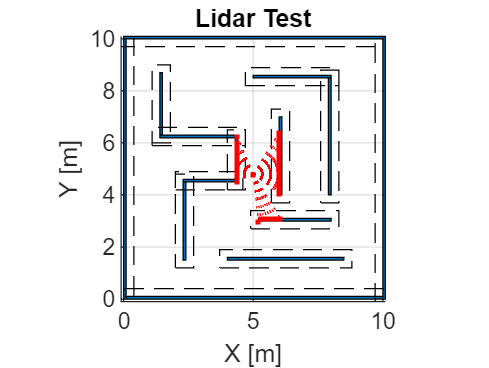

figure();
% Plot obstacles
for i = 1:size(obstacles, 1)
    hold on
    rectangle('Position', obstacles(i, :), 'FaceColor', '#0072BD');
end
% Plot inflated obstacles
for i = 1:size(inflated_obstacles, 1)
    rectangle('Position', inflated_obstacles(i, :), 'EdgeColor', 'k', 'LineStyle', '--');
end
% Plot LiDAR result
for angle_step = 1:length(lidar_angles)-1
    angle = lidar_angles(angle_step);
    ray_direction = [cosd(angle), sind(angle)];
    hit_point = point_abs(angle_step, :);
    if ~all(hit_point == 0) % Plot just hit points

        plot([lidar_position(1), hit_point(1)], [lidar_position(2), hit_point(2)],'LineStyle', ':', 'Color', 'red', 'Marker' , "."'); % Plot ray
    end
end
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
xlim([-0.10 x_map_size + 0.1]);
ylim([-0.10 y_map_size + 0.1]);
title('Lidar Test');
hold off;

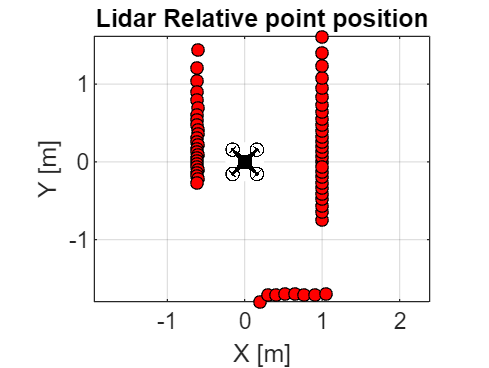


% Plot LiDAR result in relative envioment
plot(point_rel(:, 1), point_rel(:, 2), 'o', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'black', 'MarkerSize', 5); % Plot ray
grid on;
axis equal; 
xlabel('X [m]');
ylabel('Y [m]');
title('Lidar Relative point position');


img = imread('drone.jpg'); % Sostituisci con il percorso dell'immagine
imageWidth = 0.5; % Larghezza desiderata dell'immagine
imageHeight = 0.5; % Altezza desiderata dell'immagine
xPos = 0 - imageWidth/2; % Posizionamento sull'asse x
yPos = 0 - imageHeight/2; % Posizionamento sull'asse y

% Aggiungi l'immagine alla posizione specificata
image('CData', img, 'XData', [xPos, xPos + imageWidth], 'YData', [yPos, yPos + imageHeight]);

#### PID control

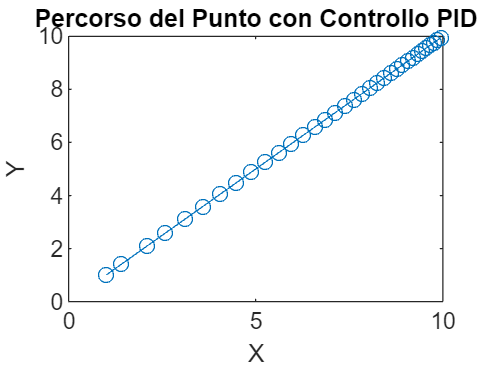

% Coefficienti PID
Kp = 1.0; % componente proporzionale
Ki = 0.1; % componente integrale
Kd = 0.5; % componente derivativa

% Posizione iniziale del punto
x = 0;
y = 0;

% Posizione della destinazione
target_x = 10;
target_y = 10;

% Errore cumulativo per l'integrale
error_sum_x = 0;
error_sum_y = 0;

% Errore precedente per il derivato
previous_error_x = target_x - x;
previous_error_y = target_y - y;

% Passo temporale (in secondi)
dt = 0.1;

% Simulazione del controllo PID
t = 0; % tempo iniziale
positions = []; % registro delle posizioni per la visualizzazione

while norm([x, y] - [target_x, target_y]) > 0.1 % continua finché non si raggiunge la destinazione
    % Errore corrente
    error_x = target_x - x;
    error_y = target_y - y;

    % Componente proporzionale
    control_p_x = Kp * error_x;
    control_p_y = Kp * error_y;

    % Componente integrale
    error_sum_x = error_sum_x + error_x * dt;
    error_sum_y = error_sum_y + error_y * dt;
    control_i_x = Ki * error_sum_x;
    control_i_y = Ki * error_sum_y;

    % Componente derivativa
    derivative_x = (error_x - previous_error_x) / dt;
    derivative_y = (error_y - previous_error_y) / dt;
    control_d_x = Kd * derivative_x;
    control_d_y = Kd * derivative_y;

    % Controllo finale
    control_x = control_p_x + control_i_x + control_d_x;
    control_y = control_p_y + control_i_y + control_d_y;

    % Aggiornamento della posizione
    x = x + control_x * dt;
    y = y + control_y * dt;

    % Memorizzazione della posizione
    positions = [positions; x, y];

    % Aggiornamento dell'errore precedente
    previous_error_x = error_x;
    previous_error_y = error_y;

    t = t + dt; % incremento del tempo
end

% Visualizzazione del percorso
figure;
plot(positions(:, 1), positions(:, 2), '-o');
xlabel('X');
ylabel('Y');
title('Percorso del Punto con Controllo PID');